# check outlier speed

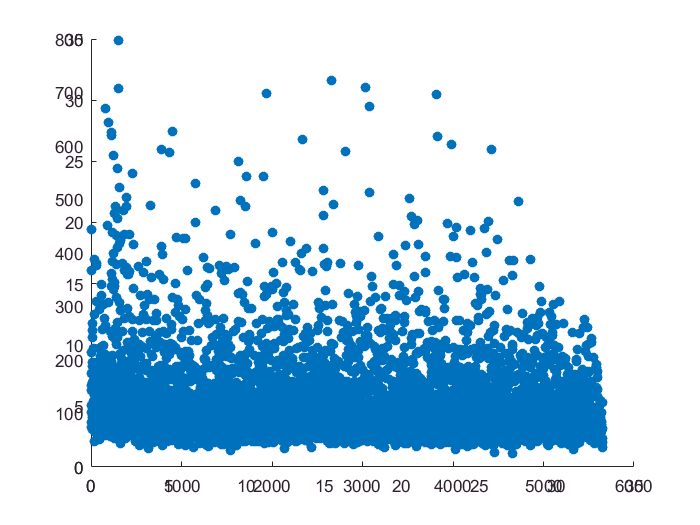

threshold = 15;
diff = zeros(length(pd.ids),2);
for m = 1:1:length(pd.ids)
    mat = pd.getRawMatById(pd.ids(m));
    vel = TrajAnalysis2D.xy2vel(mat(:,2:3),0.1,0);
    diff(m,:) = [pd.ids(m),(max(vel)-mean(vel))/std(vel)];
end
scatter(diff(:,1),diff(:,2),'filled')

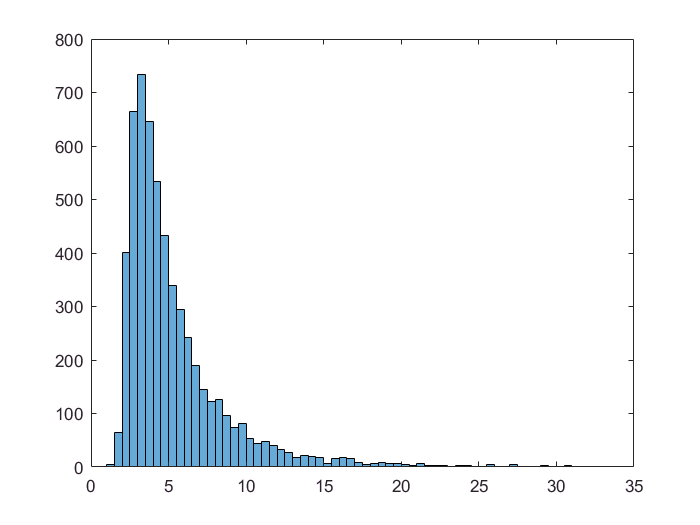

figure; histogram(diff(:,2))

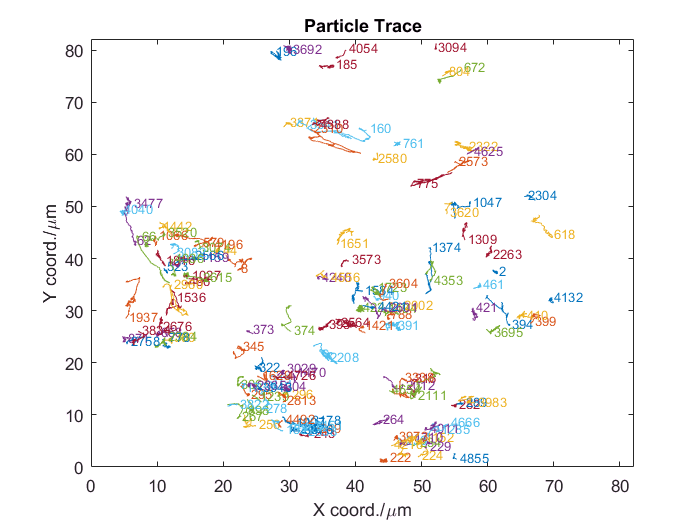

ids = diff(diff(:,2)>threshold,1);
figure;pd.plotTrace(axes,ids,1)

## show outlier

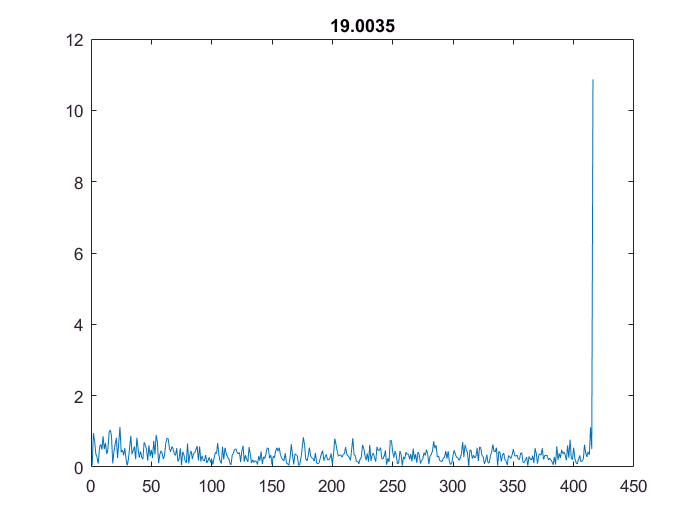

id = 373;
mat=pd.getRawMatById(id);
vel = TrajAnalysis2D.xy2vel(mat(:,2:3),0.1,0);
figure;plot(vel);title(num2str((max(vel)-mean(vel))/std(vel)))

## new

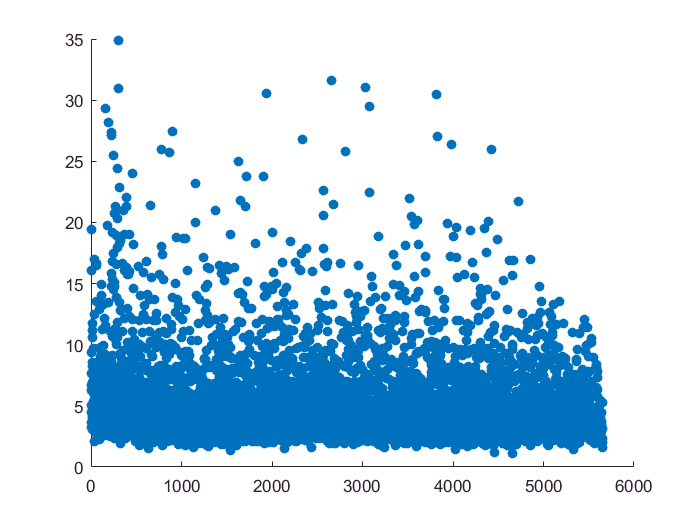

threshold = 15;
ids = TrajAnalysis2D.findVelOutlier(pd,threshold,1);

## fix

mat2 =    1.0e+03 *

    1.1240    0.0559    0.0580
    1.1250    0.0559    0.0580
    1.1260    0.0559    0.0581
    1.1270    0.0560    0.0581
    1.1280    0.0560    0.0581
    1.1290    0.0560    0.0581
    1.1300    0.0561    0.0582
    1.1310    0.0561    0.0582
    1.1320    0.0561    0.0582
    1.1330    0.0562    0.0582


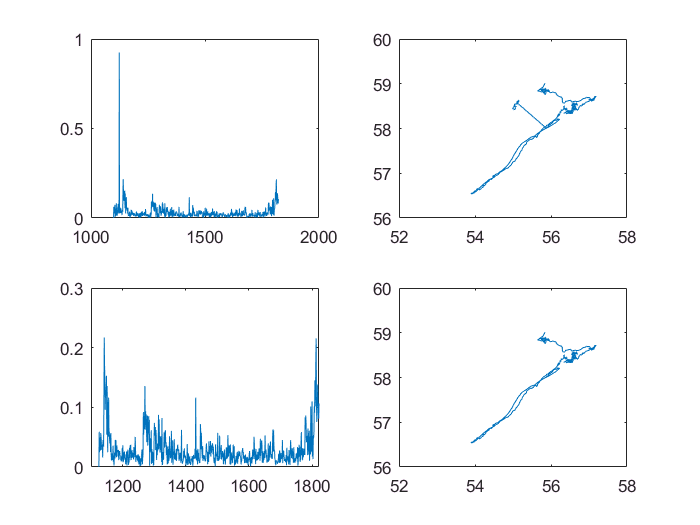

id = 2573;
mat=pd.getRawMatById(id);
mat2 = TrajAnalysis2D.fixOutlierVel(mat,15,0.1,1)